# **Hidden Markov Models (Practical and Assignment)**

**Bianca Caissotti di Chiusano **

**For the purpose of the assignment I kept the practical as part of the assignment as it helps to explain the future computations**

The new corona virus contains just a few genes, one of them is a nucleocapsid phosphoprotein, known as N.  The accession code for the RNA for the whole Coronavirus 2 genome is NC_045512.  The N protein can be found in the region 28274...29533.

- First download the full sequence, extract the part of the sequence for the N protein and make a nucleotide density plot with a suitable window size. Showing the distribution of each base across the sequence and also the AT and GC pairs. 

covid2 = getgenbank('NC_045512', "SequenceOnly",true)

covid2 = 'ATTAAAGGTTTATACCTTCCCAGGTAACAAACCAACCAACTTTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGGCTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCGTCTATCTTCTGCAGGCTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTTTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGTCTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGCGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCGGATGCTCGAACTGCACCTCATGGTCATGTTATGGTTGAGCTGGTAGCAGAACTCGAAGGCATTCAGTACGGTCGTAGTGGTGAGACACTTGGTGTCCTTGTCCCTCATGTGGGCGAAATACCAGTGGCTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCCGATCTAAAGTCATTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTTACCCGTGAACTCATGCGTGAGCTTAACGGAGGGGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCACGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAGAGGGGTGTATACTGCTGCCGTGAACATGAGCATGAAATTGCTTGGTACAC

N_protein = getgenbank('NC_045512', "SequenceOnly",true, "PartialSeq",[28274,29533])

N_protein = 'ATGTCTGATAATGGACCCCAAAATCAGCGAAATGCACCCCGCATTACGTTTGGTGGACCCTCAGATTCAACTGGCAGTAACCAGAATGGAGAACGCAGTGGGGCGCGATCAAAACAACGTCGGCCCCAAGGTTTACCCAATAATACTGCGTCTTGGTTCACCGCTCTCACTCAACATGGCAAGGAAGACCTTAAATTCCCTCGAGGACAAGGCGTTCCAATTAACACCAATAGCAGTCCAGATGACCAAATTGGCTACTACCGAAGAGCTACCAGACGAATTCGTGGTGGTGACGGTAAAATGAAAGATCTCAGTCCAAGATGGTATTTCTACTACCTAGGAACTGGGCCAGAAGCTGGACTTCCCTATGGTGCTAACAAAGACGGCATCATATGGGTTGCAACTGAGGGAGCCTTGAATACACCAAAAGATCACATTGGCACCCGCAATCCTGCTAACAATGCTGCAATCGTGCTACAACTTCCTCAAGGAACAACATTGCCAAAAGGCTTCTACGCAGAAGGGAGCAGAGGCGGCAGTCAAGCCTCTTCTCGTTCCTCATCACGTAGTCGCAACAGTTCAAGAAATTCAACTCCAGGCAGCAGTAGGGGAACTTCTCCTGCTAGAATGGCTGGCAATGGCGGTGATGCTGCTCTTGCTTTGCTGCTGCTTGACAGATTGAACCAGCTTGAGAGCAAAATGTCTGGTAAAGGCCAACAACAACAAGGCCAAACTGTCACTAAGAAATCTGCTGCTGAGGCTTCTAAGAAGCCTCGGCAAAAACGTACTGCCACTAAAGCATACAATGTAACACAAGCTTTCGGCAGACGTGGTCCAGAACAAACCCAAGGAAATTTTGGGGACCAGGAACTAATCAGACAAGGAACTGATTACAAACATTGGCCGCAAATTGCACAATTTGCCCCCAGCGCTTCAGCGTTCTTCGGAATGTCGCGCATTGGCATGGAAGTCACACCTTCGGGAACG

I chose to work with window size 100 as it helped me visualise the shifts ATRich and CGRich in the A-T C-G density plot clearer. ATRich and CG Rich are going to be the two chosen states

I also create this array of 354 character called HighCG to keep track of when CG is higher than the threshold 0.5.

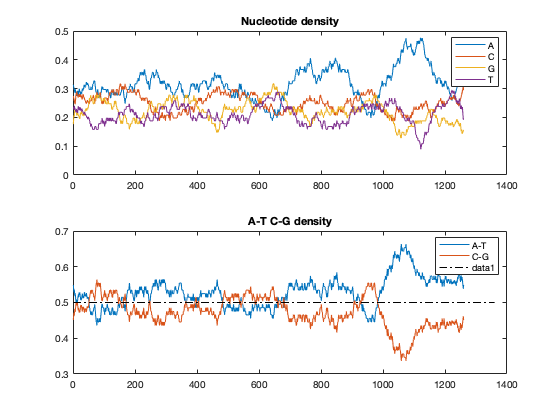

protein_density = struct with fields:
    A: [1×1260 double]
    C: [1×1260 double]
    G: [1×1260 double]
    T: [1×1260 double]


HighCG =     52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101


[protein_density, HighCG] = ntdensity(N_protein, 'Window', 100, 'CGThreshold', 0.5)

        2. To start training a hidden Markov model we first need to estimate the E and T matrices. *Explain what these matrices are. *

*E: Emissions Matrix - Probability of each symbol being observed in a sequence being generated by each state*

*T: Transition Matrix - Probability of transitions between states*

        3.  Our Hidden Markov model will have 2 states, and we expect transitions between states to be rare. Use this information to estimate T. 

Here we keep track of all the total number of each base in the protein.

% Use this for probability
all_bases = basecount(N_protein)

all_bases = struct with fields:
    A: 400
    C: 315
    G: 280
    T: 265


% Not sure if this is useful
dimer_count = dimercount(N_protein)

dimer_count = struct with fields:
    AA: 151
    AC: 91
    AG: 86
    AT: 71
    CA: 124
    CC: 68
    CG: 39
    CT: 84
    GA: 81
    GC: 85
    GG: 71
    GT: 43
    TA: 43
    TC: 71
    TG: 84
    TT: 67


# **For 2 States**

To estimate the E matrix, we start for state 1, thus CGRich. 

For each nucleotide of the protein in position considered to be HighCG we check, wether it is A,C,G or T. Keeping track of everything with counters.

At the end we calculate the probability of each nucleotide occurring in state 1, by dividing the total number of nucleotide A,C,G or T by the length of state1.

% Calculate the number of A, C, G, T in every High CG

CounterA = 0;
CounterC = 0;
CounterG = 0;
CounterT = 0;

for i = 1 : length(HighCG)
    nucleotide = N_protein(HighCG(i));
    if nucleotide == 'A'
        CounterA = CounterA+1;
    elseif nucleotide =='C'
        CounterC = CounterC+1;
    elseif nucleotide == 'G'
        CounterG = CounterG+1;
    else
        CounterT = CounterT+1;
    end
    
end

%CounterA
%CounterC
%CounterG
%CounterT
% Emissions matrix: Probability of each symbol being observed in a sequence being generated by each state
E_A = CounterA/length(HighCG);
E_C = CounterC/length(HighCG);
E_G = CounterG/length(HighCG);
E_T = CounterT/length(HighCG);

Every other position in the protein that is not CGHigh, is then considered to be in ATHigh, so we calculate the length of state 2.

ATHigh_length = length(N_protein) - length(HighCG)

ATHigh_length = 906

And we use the basecount previously executed to get the number of nucleotides A,C,G or T in ATHigh. And estimating the E matrix for state 2 as we did for state 2.

AT_A = all_bases.A - CounterA;
AT_C = all_bases.C - CounterC;
AT_G = all_bases.G - CounterG;
AT_T = all_bases.T - CounterT;
E2_A = AT_A/ATHigh_length;
E2_C = AT_C/ATHigh_length;
E2_G = AT_G/ATHigh_length;
E2_T = AT_T/ATHigh_length;
% guessTR and guessE
%number of switches is 13 - length of CG high is 440
P_state1_to_2 = 3./length(HighCG);
P_state1_to_1 = 1-P_state1_to_2;
P_state2_to_1 = 3./ATHigh_length;
P_state2_to_2 = 1-P_state2_to_1;
guessE = [[E_A, E_C, E_G, E_T]; [E2_A, E2_C, E2_G, E2_T]]

guessE =     0.2429    0.2768    0.2627    0.2175
    0.3466    0.2395    0.2064    0.2075


Initially, I tried to estimate the Transition matrix, by dividing the number of "switches" between states observed (thus 3), by the length of state 1 and state 2 respectively. 

guessT = [[P_state1_to_2, P_state1_to_1];[P_state2_to_2,P_state2_to_1]]

guessT =     0.0085    0.9915
    0.9967    0.0033


However, I then opted to guessing the Transition matrix value, by just assigning the probability of 0.95 of staying in the same state and 0.05 of switching to the other state, for both states.

guessT_2 = [0.95,0.05;0.05,0.95];

        5. Before we can train the hidden Markov model we need to turn the sequence into integers instead of characters – use **nt2int** to do this. 

N_protein_new = nt2int(N_protein)

N_protein_new = 1×1260 uint8 row vector
   1   4   3   4   2   4   3   1   4   1   1   4   3   3   1   2   2   2   2   1   1   1   1   4   2   1   3   2   3   1   1   1   4   3   2   1   2   2   2   2   3   2   1   4   4   1   2   3   4   4


        6. Now we can train our hmm using **hmmtrain** (NB. to speed this up you can change the tolerance parameter). This gives us the learnt E and T matrices based on this sequence. How do these vary from your initial guesses? 

[ESTTR,ESTEMIT] = hmmtrain(N_protein_new, guessT_2, guessE)

ESTTR =     0.6181    0.3819
    0.3365    0.6635


ESTEMIT =     0.0000    0.2656    0.2920    0.4424
    0.5976    0.2362    0.1607    0.0055


        7. To look at how this HMM would segment your sequence, use the function **hmmviterbi** to generate the estimated states from this sequence.  

estimated_states = hmmviterbi(N_protein_new,ESTTR,ESTEMIT)

estimated_states =      2     1     1     1     1     1     1     2     1     2     2     1     1     1     2     2     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2     2     1     1     1     2     2     2     2     2     2     2     2     1     1     2     1     1     1     1


        8. Using the **hold** function add these states onto the **ntdensity** plot. How does this help your interpretation of the states? Can you explain what the two states mean? 

density = ntdensity(N_protein, 'Window', 100)

density = struct with fields:
    A: [1×1260 double]
    C: [1×1260 double]
    G: [1×1260 double]
    T: [1×1260 double]


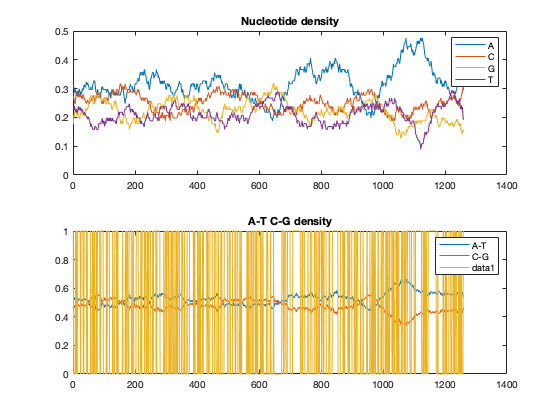

hold on
plot(estimated_states-1)
hold off

**Assignment:**

Try building HMMs with different numbers of states on this sequence.  Which number of states works best?  Explain your best model, interpreting the states (explain how they are different from each other, no biological interpretation needed).  

# **For 3 States**

To decide the three states, I chose the following looking at the Nucleotide density plot:

State 1:  from positions 0-580 and 1201-1260 --> A,C,G,T more or less random

State 2: from  positions 581-700 and 901-1000 --> A,C,G,T more or less the same

State 3: from positions 701-900 and 1001-1200 --> A much higher and T much lower

For each state, the Emissions matrix was estimated by getting the subsequences of the protein in the specified positions, using basecount to count the nucleotides in each of the subsequences

and keeping track of everything with counters for each nucleotide. 

protein_density = ntdensity(N_protein, 'Window', 100)

protein_density = struct with fields:
    A: [1×1260 double]
    C: [1×1260 double]
    G: [1×1260 double]
    T: [1×1260 double]


% State 1: 0-580 and 1201-1260 --> A,C,G,T more or less random
length_state1 = 0;
length_state2 = 0;
length_state3 = 0;

three_countA = 0;
three_countC = 0;
three_countG = 0;
three_countT = 0;

state1_1 = N_protein(1:580);
state1_2 = N_protein(1201:1260);
countBase = basecount(state1_1);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

countBase = basecount(state1_2);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

tot_len = length(state1_1)+length(state1_2)

tot_len = 640

E_3_1_A = three_countA./tot_len;
E_3_1_C = three_countC./tot_len;
E_3_1_G = three_countG./tot_len;
E_3_1_T = three_countT./tot_len;
E_trial_1 = [E_3_1_A,E_3_1_C,E_3_1_G,E_3_1_T];
% State 2
% State 2: 581-700 and 901-1000 --> A,C,G,T more or less the same
three_countA = 0;
three_countC = 0;
three_countG = 0;
three_countT = 0;

state2_1 = N_protein(581:700);
state2_2 = N_protein(901:1000);
countBase = basecount(state2_1);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

countBase = basecount(state2_2);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

tot_len = length(state2_1)+length(state2_2)

tot_len = 220

E_3_2_A = three_countA./tot_len;
E_3_2_C = three_countC./tot_len;
E_3_2_G = three_countG./tot_len;
E_3_2_T = three_countT./tot_len;
E_trial_2 = [E_3_2_A,E_3_2_C,E_3_2_G,E_3_2_T];


% State 3
% State 3: 701-900 and 1001-1200 --> A much higher and T much lower
three_countA = 0;
three_countC = 0;
three_countG = 0;
three_countT = 0;

state3_1 = N_protein(701:900);
state3_2 = N_protein(1001:1200);
countBase = basecount(state3_1);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

countBase = basecount(state3_2);
three_countA = three_countA + countBase.A;
three_countC = three_countC + countBase.C;
three_countG = three_countG + countBase.G;
three_countT = three_countT + countBase.T;

tot_len = length(state3_1)+length(state3_2)

tot_len = 400

E_3_3_A = three_countA./tot_len;
E_3_3_C = three_countC./tot_len;
E_3_3_G = three_countG./tot_len;
E_3_3_T = three_countT./tot_len;
E_trial_3 = [E_3_3_A,E_3_3_C,E_3_3_G,E_3_3_T];
guessE = [E_trial_1; E_trial_2; E_trial_3]

guessE =     0.3047    0.2625    0.2219    0.2109
    0.2364    0.2545    0.2682    0.2409
    0.3825    0.2275    0.1975    0.1925


Also this time I still opted for the same reasoning of the transition matrix

guessT = [0.95,0.025, 0.025;0.025,0.95,0.025;0.025,0.025,0.95];
guessT_2 = [0.90,0.05, 0.05;0.05,0.90,0.05;0.05,0.05,0.90]

guessT_2 =     0.9000    0.0500    0.0500
    0.0500    0.9000    0.0500
    0.0500    0.0500    0.9000


[ESTTR,ESTEMIT] = hmmtrain(N_protein_new, guessT, guessE)

ESTTR =     0.7076    0.0013    0.2911
    0.4442    0.4501    0.1056
    0.0347    0.9083    0.0569


ESTEMIT =     0.4534    0.3432    0.0991    0.1043
    0.0003    0.2491    0.5525    0.1981
    0.4841    0.0057    0.0001    0.5102


estimated_states = hmmviterbi(N_protein_new,ESTTR,ESTEMIT)

estimated_states =      1     3     2     2     1     3     2     1     1     1     1     3     2     2     1     1     1     1     1     1     1     1     1     1     1     3     2     2     2     1     1     1     3     2     1     1     1     1     1     1     1     1     1     3     2     1     1     1     3     2


[ESTTR_2,ESTEMIT_2] = hmmtrain(N_protein_new, guessT_2, guessE)

ESTTR_2 =     0.5555    0.0067    0.4378
    0.4879    0.4392    0.0729
    0.2610    0.6146    0.1244


ESTEMIT_2 =     0.4181    0.4211    0.1284    0.0324
    0.0009    0.1765    0.5736    0.2491
    0.4884    0.0218    0.0001    0.4896


estimated_states_2 = hmmviterbi(N_protein_new,ESTTR_2,ESTEMIT_2)

estimated_states_2 =      1     3     2     2     1     3     2     1     3     1     1     3     2     2     1     1     1     1     1     1     1     1     3     2     1     3     2     2     2     1     1     1     3     2     1     1     1     1     1     1     1     1     1     3     2     1     1     1     3     2


density = ntdensity(N_protein, 'Window', 100)

density = struct with fields:
    A: [1×1260 double]
    C: [1×1260 double]
    G: [1×1260 double]
    T: [1×1260 double]


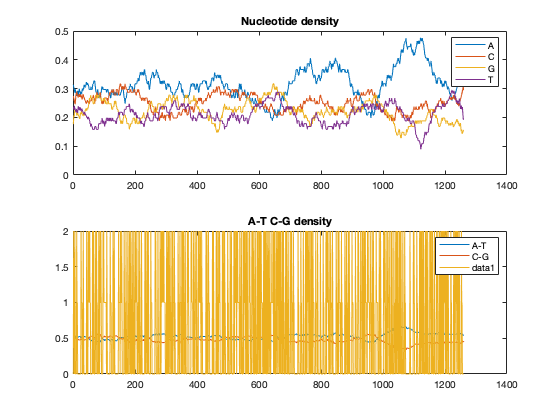

hold on
plot(estimated_states-1)
hold off

To me it looks like, because there are three states, there are more lines, thus less intuitive. I belive it all comes down to how you decide the states. Of course, this protein is not like just creating a sequence

from a fair or unfair dice (like the 2 state problem), thus there are many more states to be found, and the distributinons of nucleotides is much more random. 